Initialization

close all
addpath myFunction\myftn
clearvars -except mapCD
fn = 'RawData\1T-TaS2(point defect)\mapCD.mat';
loadif(fn);

fldNm = 1×1 cell array
    {'mapCD'}



Your variables are:

fldNm  fn     mt     



load RawData\'1T-TaS2(point defect)'\vDos.mat vDos

## Determine Lattice Parameters for Line profile

determine parameter

xsC = 5

xsC = 5

xeC = 551

xeC = 551

NC = 43

NC = 43


xsA = 9

xsA = 9

xeA = 725

xeA = 725

NA = 56

NA = 56


line_info(:,:,1) = [xsC xeC NC;xsA xeA NA]

line_info =      5   551    43
     9   725    56


line_info(:,:,2) = [10 609 41;11 611 41]

line_info = line_info(:,:,1) =

     5   551    43
     9   725    56


line_info(:,:,2) =

    10   609    41
    11   611    41


Confirm line profile

gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(1,:),[0 0 1 1]);
f1.Visible = "on";

Visualization

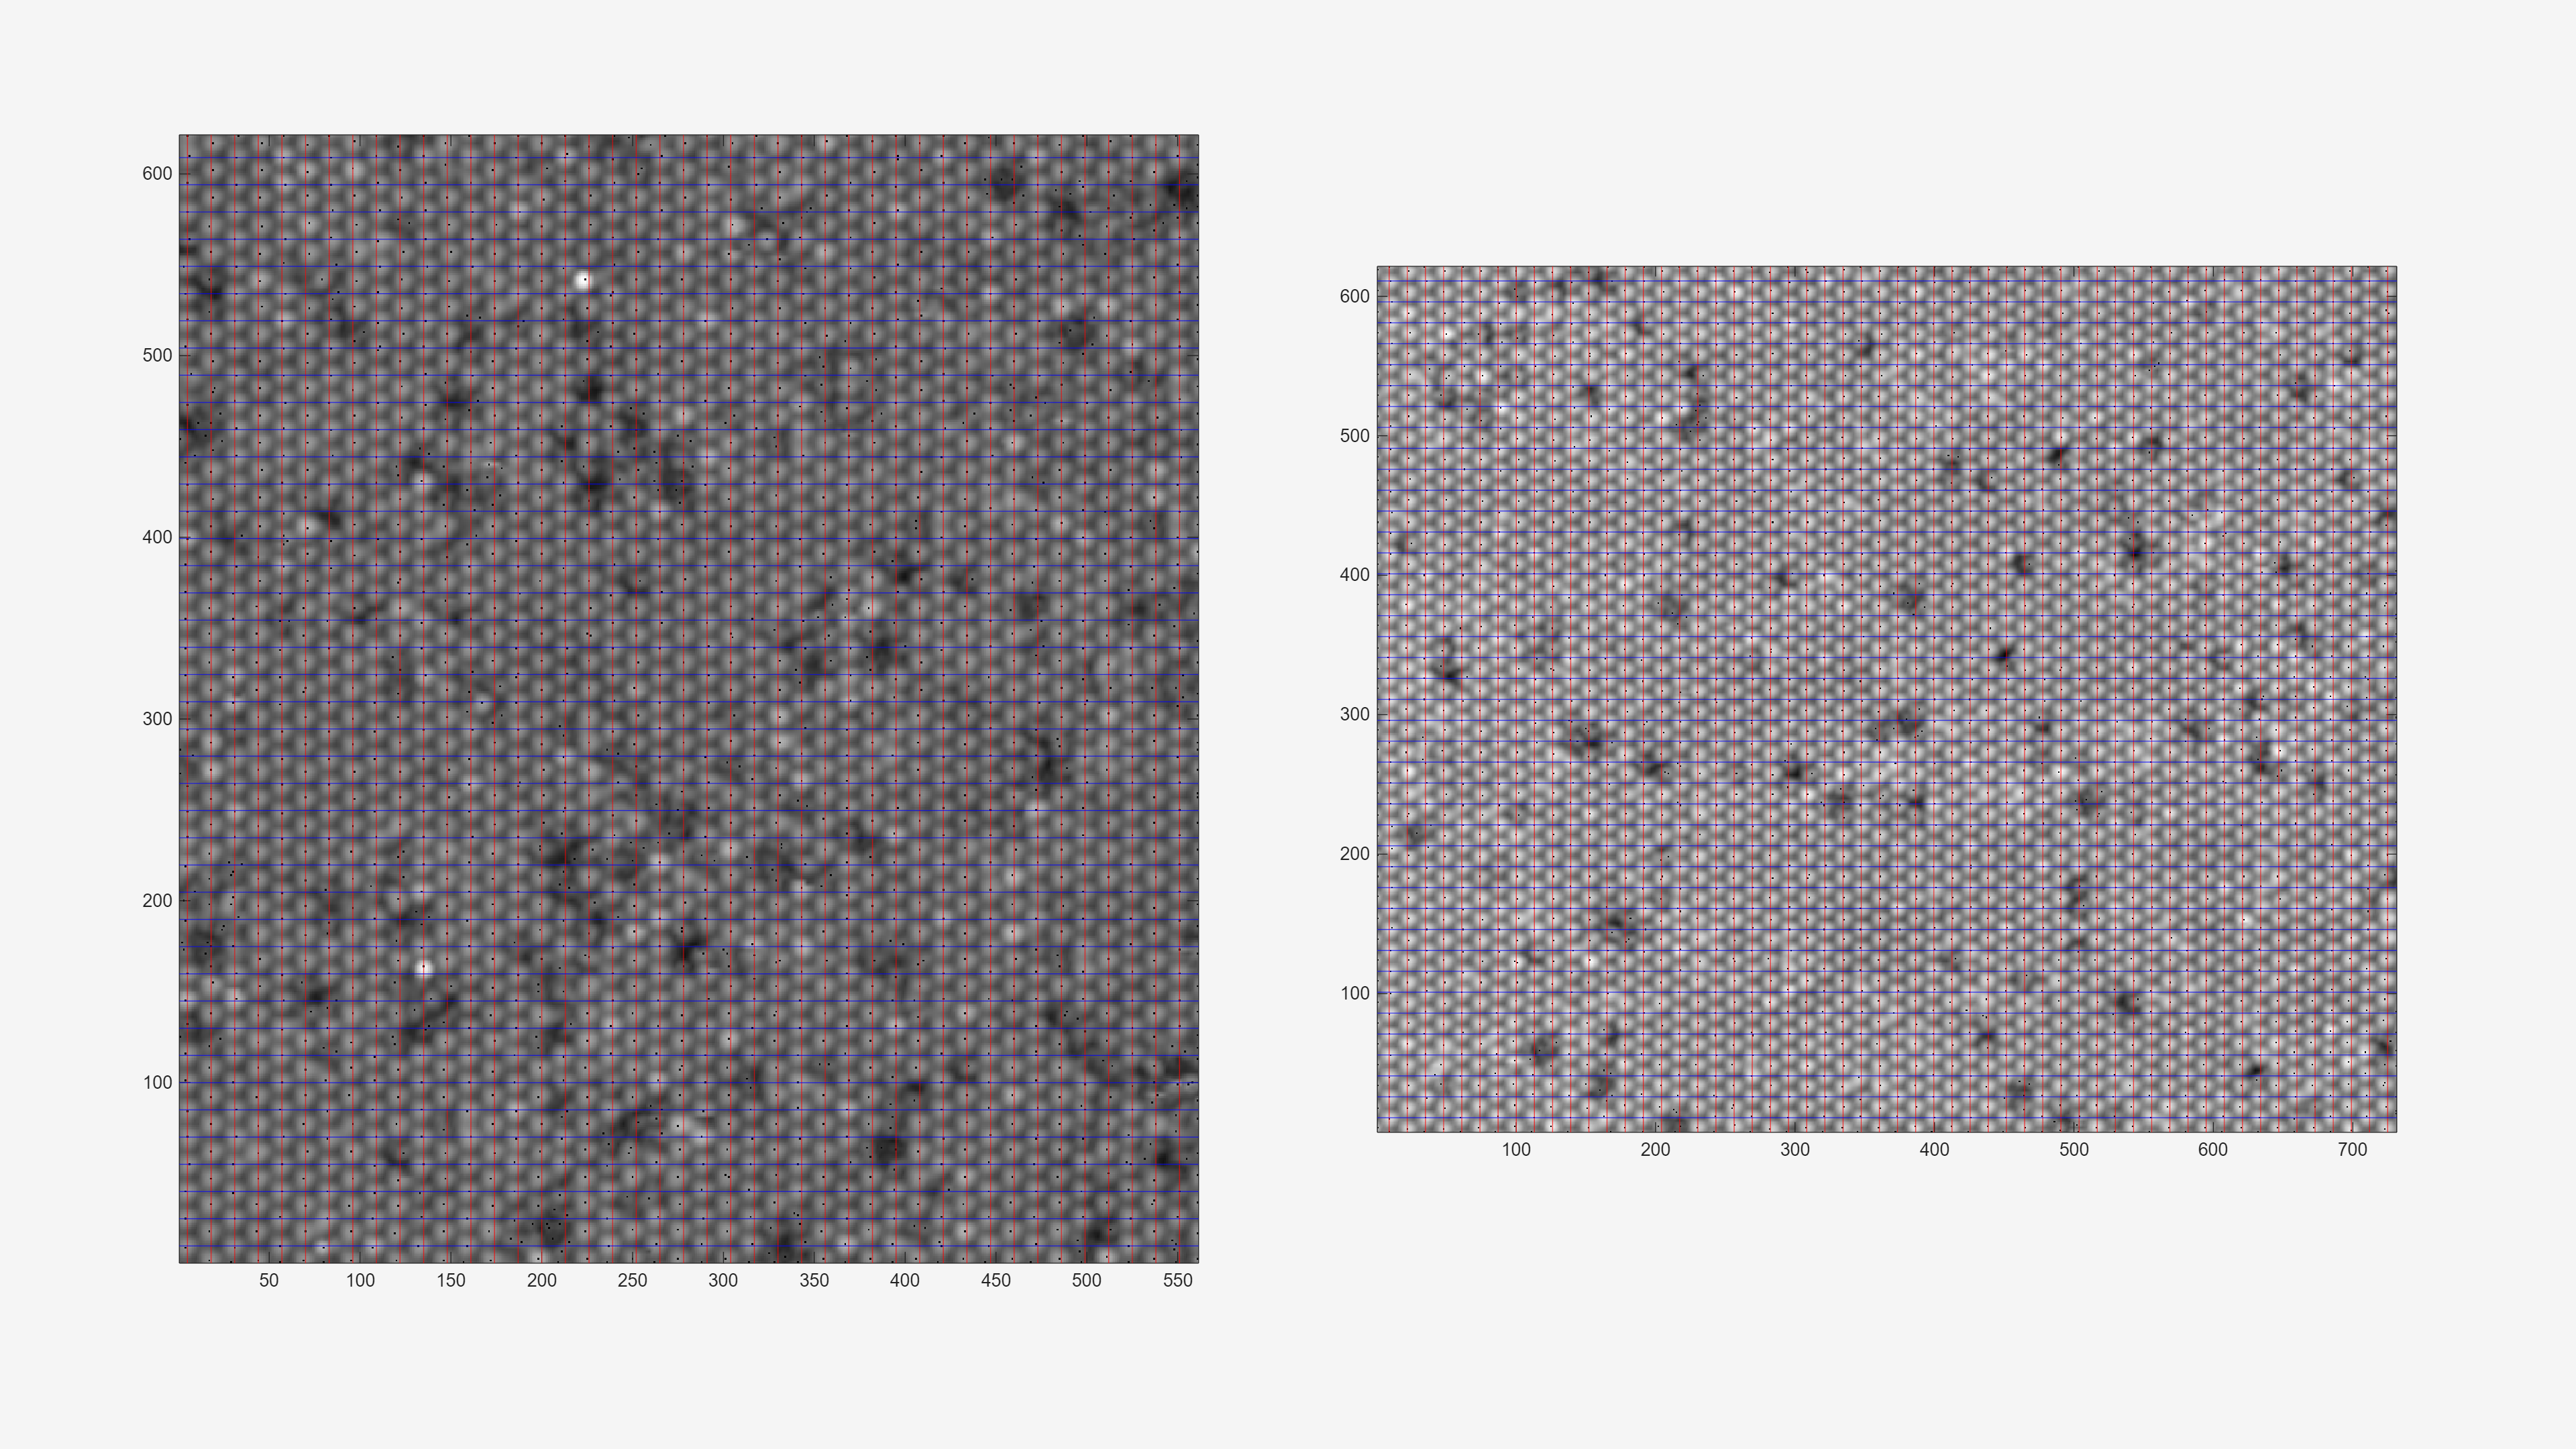

xlns =      5    18    31    44    57    70    83    96   109   122   135   148   161   174   187   200   213   226   239   252   265   278   291   304   317   330   343   356   369   382   395   408   421   434   447   460   473   486   499   512   525   538   551


ylns =    10.0000   24.9750   39.9500   54.9250   69.9000   84.8750   99.8500  114.8250  129.8000  144.7750  159.7500  174.7250  189.7000  204.6750  219.6500  234.6250  249.6000  264.5750  279.5500  294.5250  309.5000  324.4750  339.4500  354.4250  369.4000  384.3750  399.3500  414.3250  429.3000  444.2750  459.2500  474.2250  489.2000  504.1750  519.1500  534.1250  549.1000  564.0750  579.0500  594.0250  609.0000


axs =   Axes with properties:

             XLim: [0.5000 561.5000]
             YLim: [0.5000 621.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.0694 0.1280 0.3958 0.7790]
            Units: 'normalized'

  Show all properties


xlns =     9.0000   22.0182   35.0364   48.0545   61.0727   74.0909   87.1091  100.1273  113.1455  126.1636  139.1818  152.2000  165.2182  178.2364  191.2545  204.2727  217.2909  230.3091  243.3273  256.3455  269.3636  282.3818  295.4000  308.4182  321.4364  334.4545  347.4727  360.4909  373.5091  386.5273  399.5455  412.5636  425.5818  438.6000  451.6182  464.6364  477.6545  490.6727  503.6909  516.7091  529.7273  542.7455  555.7636  568.7818  581.8000  594.8182  607.8364  620.8545  633.8727  646.8909


ylns =     11    26    41    56    71    86   101   116   131   146   161   176   191   206   221   236   251   266   281   296   311   326   341   356   371   386   401   416   431   446   461   476   491   506   521   536   551   566   581   596   611


axs =   1×2 Axes array:

    Axes    Axes


tiledlayout(1,2)

for iphase = 1:2
    nexttile
    Z = mapCD.dt(iphase).Z;
    loc_max = ~imregionalmax(Z,8);
    views(Z.*loc_max)    
    colormap gray
    xlns = linspace(line_info(iphase,1,1),line_info(iphase,2,1),line_info(iphase,3,1))
    ylns = linspace(line_info(iphase,1,2),line_info(iphase,2,2),line_info(iphase,3,2))
    xline(xlns,'r')
    yline(ylns,'b')
    axs(iphase) = gca()
end

## Determine Lattice Parameters for Unitcell analysis

iphase = 1;
M1 = [1 1/2;0 1];
lf = line_info;
m2_11 = (lf(iphase,2,1) - lf(iphase,1,1))/(lf(iphase,3,1)-1);
m2_22 = (lf(iphase,2,2) - lf(iphase,1,2))/(lf(iphase,3,2)-1);
M2 = [m2_11 0; 0 m2_22];
M = M1*M2;
O = squeeze(lf(1,1,:));

nmList = []


nmList =

     []



for nNow =-1:20
    for mNow = -1:20
        nmNow = [nNow mNow];
        nmNow;
        nmList = [nmList;nmNow];
    end
end
% nmList = nmList';

xyList =  nmList *M+ O';
xyList = xyList'

xyList =    -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000   -8.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000   18.0000   18.0000   18.0000   18.0000   18.0000   18.0000
  -12.4625    2.5125   17.4875   32.4625   47.4375   62.4125   77.3875   92.3625  107.3375  122.3125  137.2875  152.2625  167.2375  182.2125  197.1875  212.1625  227.1375  242.1125  257.0875  272.0625  287.0375  302.0125   -4.9750   10.0000   24.9750   39.9500   54.9250   69.9000   84.8750   99.8500  114.8250  129.8000  144.7750  159.7500  174.7250  189.7000  204.6750  219.6500  234.6250  249.6000  264.5750  279.5500  294.5250  309.5000    2.5125   17.4875   32.4625   47.4375   62.4125

f1 =gcf()

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [0 0 1 1]
       Units: 'normalized'

  Show all properties


f1.CurrentAxes = axs(1)

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [0 0 1 1]
       Units: 'normalized'

  Show all properties


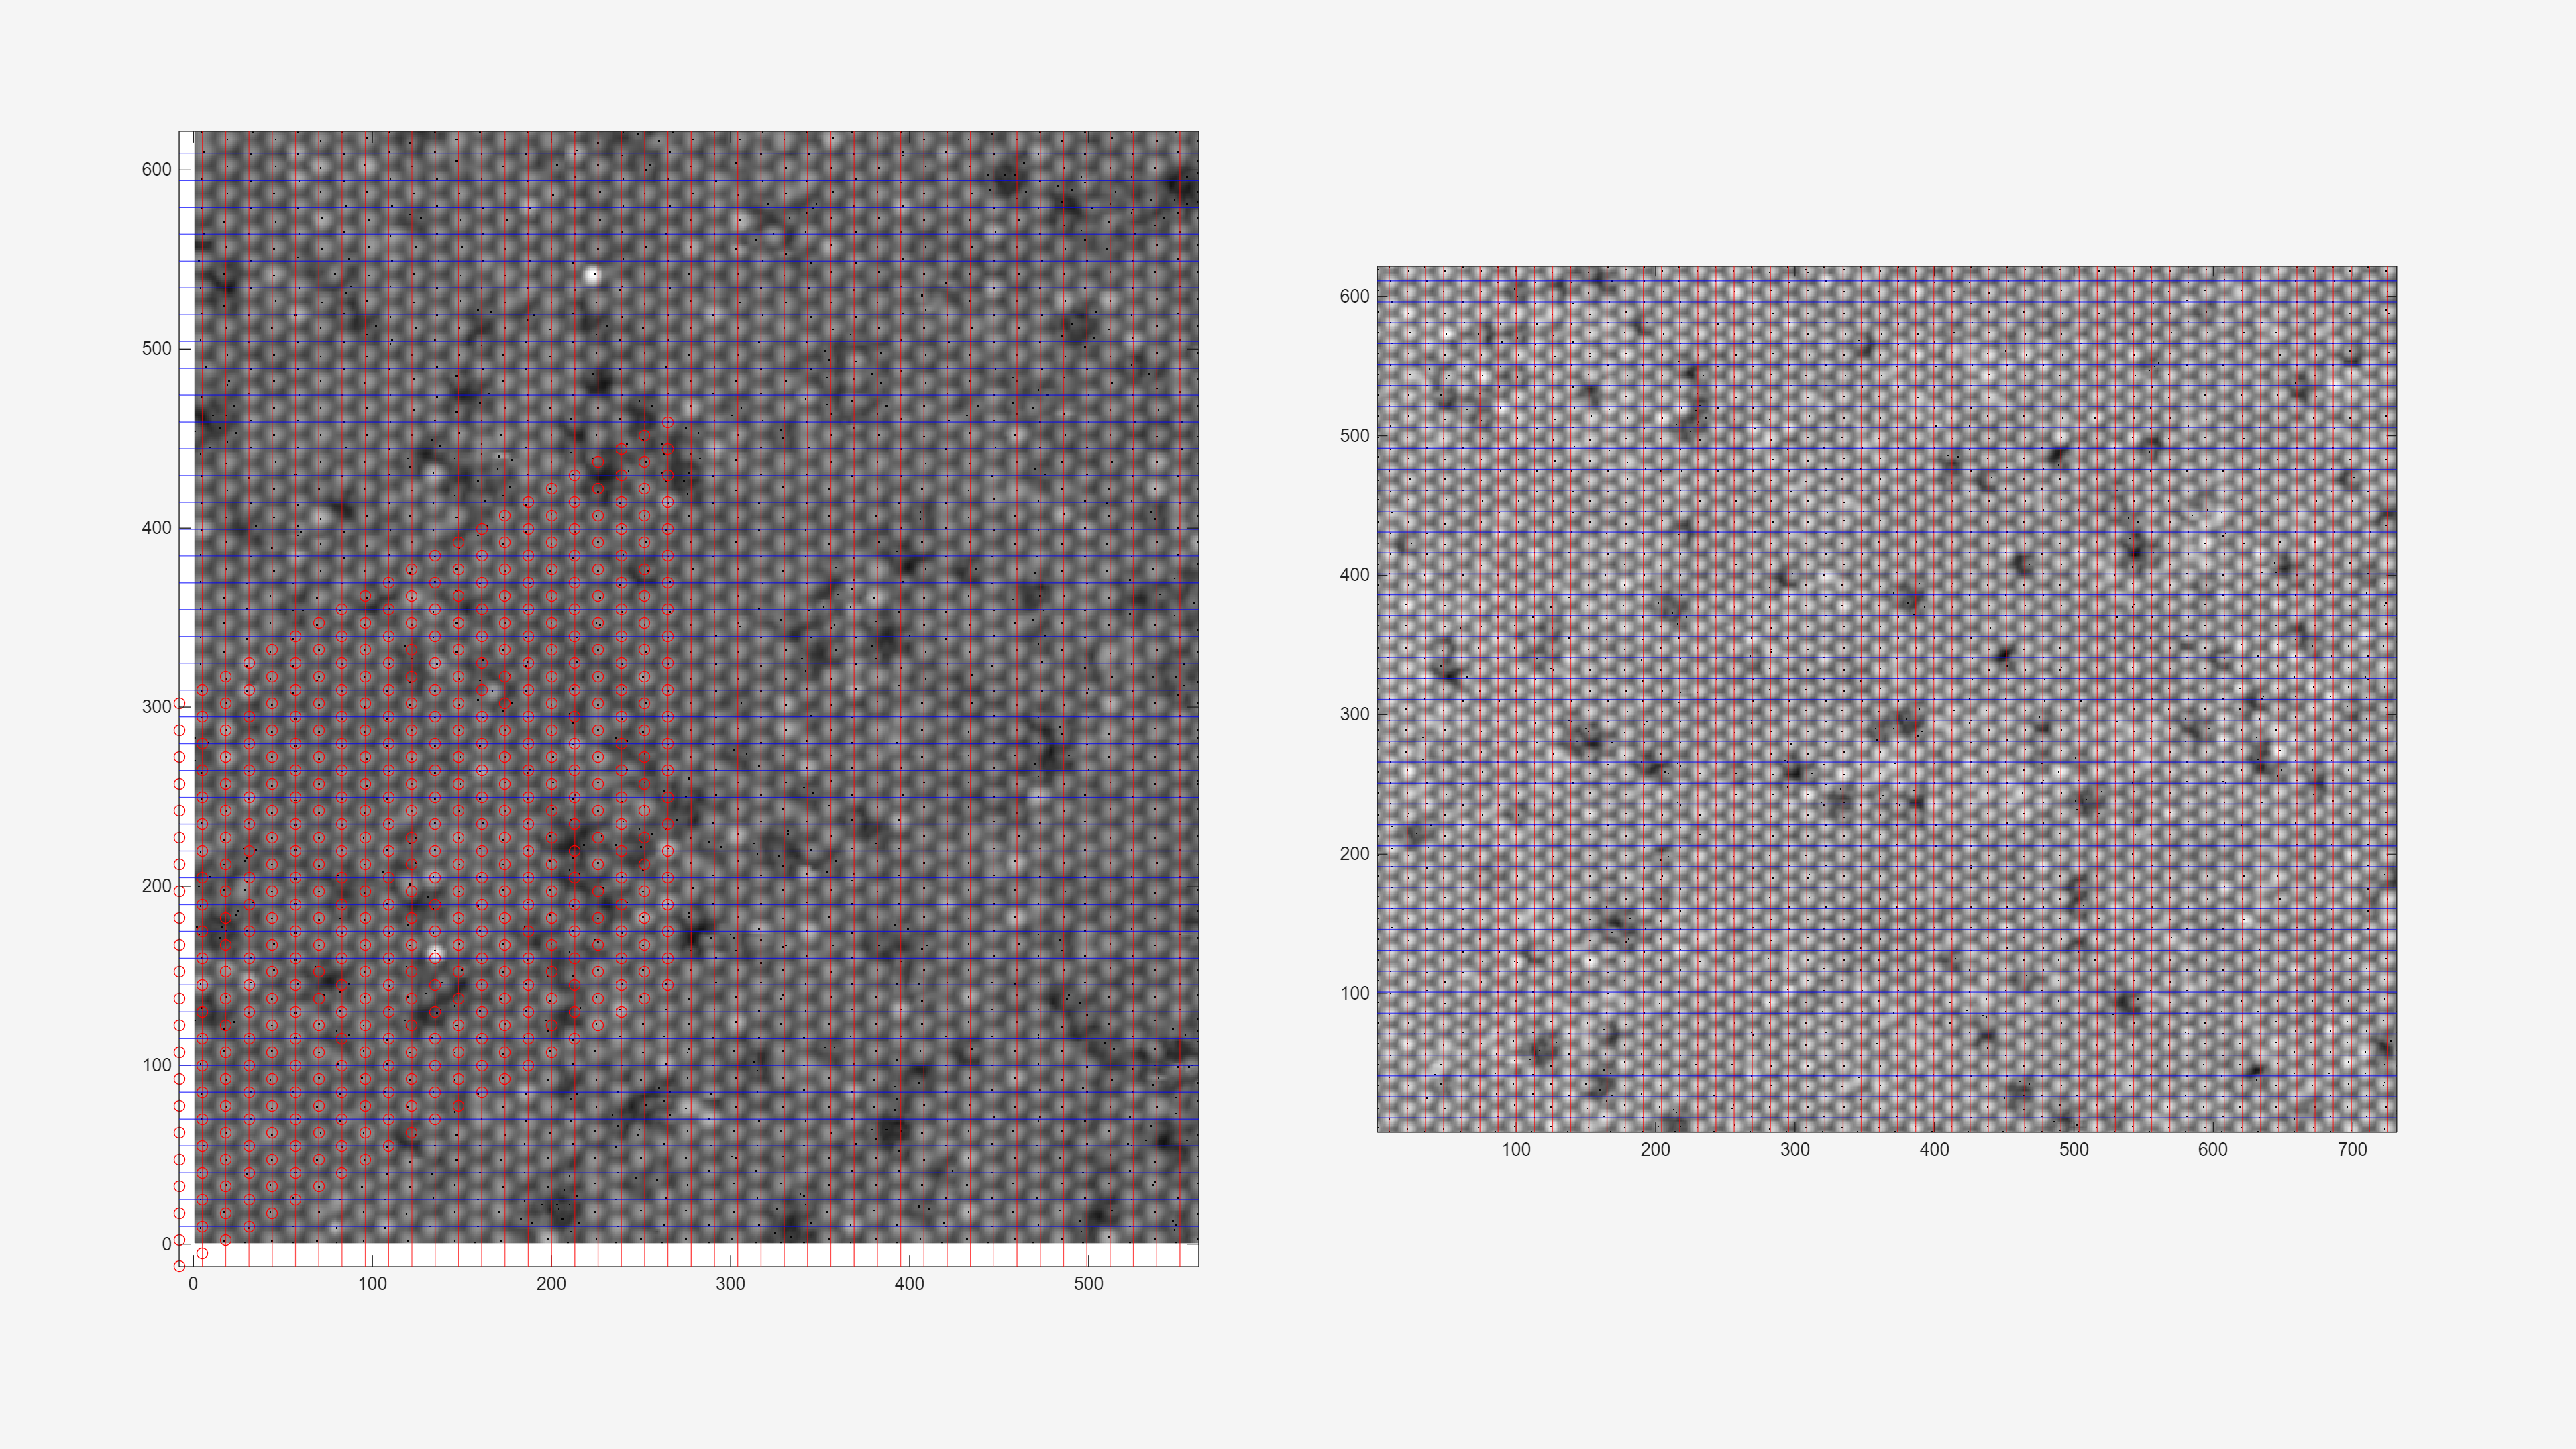

hold on
plot(xyList(1,:),xyList(2,:),'ro')
hold off

save griding

grd.hd.from = currentScript

grd = struct with fields:
    hd: [1×1 struct]


grd.hd.index.line_info = ["1st:phase 2nd:start,end,N 3rd:x or y"]

grd = struct with fields:
    hd: [1×1 struct]


grd.line_info = line_info

grd = struct with fields:
           hd: [1×1 struct]
    line_info: [2×3×2 double]


save RawData\'1T-TaS2(point defect)'\grd.mat grd